
clc 
T = linspace(15,80,100) 

T =    15.0000   15.6566   16.3131   16.9697   17.6263   18.2828   18.9394   19.5960   20.2525   20.9091   21.5657   22.2222   22.8788   23.5354   24.1919   24.8485   25.5051   26.1616   26.8182   27.4747   28.1313   28.7879   29.4444   30.1010   30.7576   31.4141   32.0707   32.7273   33.3838   34.0404   34.6970   35.3535   36.0101   36.6667   37.3232   37.9798   38.6364   39.2929   39.9495   40.6061   41.2626   41.9192   42.5758   43.2323   43.8889   44.5455   45.2020   45.8586   46.5152   47.1717




% Source for data 
% http://ddbonline.ddbst.com/AntoineCalculation/AntoineCalculationCGI.exe
% Vapor Pressure for Methanol 
A_m = 8.08097; 
B_m = 1582.27; 
C_m = 239.7; 
P_methanol = 10.^(A_m - (B_m./(C_m+T))) ;
P_methanol = P_methanol./760 % converting from mmHg to atm 

P_methanol =     0.0972    0.1009    0.1046    0.1085    0.1125    0.1167    0.1209    0.1253    0.1298    0.1345    0.1393    0.1443    0.1494    0.1546    0.1600    0.1656    0.1714    0.1773    0.1834    0.1896    0.1961    0.2027    0.2095    0.2166    0.2238    0.2312    0.2388    0.2467    0.2547    0.2630    0.2715    0.2803    0.2892    0.2985    0.3079    0.3177    0.3277    0.3379    0.3484    0.3592    0.3703    0.3817    0.3933    0.4053    0.4175    0.4301    0.4430    0.4562    0.4698    0.4837



% Vapor Pressure for Ethanol
A_e = 8.20417; 
B_e = 1642.89; 
C_e = 230.3; 
P_ethanol = 10.^(A_e - B_e./(C_e+T)) ;
P_ethanol = P_ethanol./760 % converting from mmHg to atm 

P_ethanol =     0.0423    0.0440    0.0459    0.0478    0.0498    0.0518    0.0539    0.0561    0.0584    0.0607    0.0632    0.0657    0.0683    0.0710    0.0738    0.0766    0.0796    0.0827    0.0858    0.0891    0.0925    0.0960    0.0996    0.1033    0.1072    0.1112    0.1153    0.1195    0.1238    0.1283    0.1330    0.1377    0.1426    0.1477    0.1529    0.1583    0.1639    0.1696    0.1755    0.1815    0.1878    0.1942    0.2008    0.2076    0.2146    0.2217    0.2291    0.2367    0.2446    0.2526



% Vapor Pressure for 1-Butanol 
A_b = 7.92484; 
B_b = 1617.52; 
C_b = 203.296; 
P_butanol = 10.^(A_b - B_b./(C_b+T)) ;
P_butanol = P_butanol./760 % converting from mmHg to atm 

P_butanol =     0.0043    0.0045    0.0048    0.0050    0.0053    0.0055    0.0058    0.0061    0.0064    0.0068    0.0071    0.0074    0.0078    0.0082    0.0086    0.0090    0.0094    0.0099    0.0103    0.0108    0.0113    0.0119    0.0124    0.0130    0.0136    0.0142    0.0148    0.0155    0.0162    0.0169    0.0177    0.0185    0.0193    0.0201    0.0210    0.0219    0.0228    0.0238    0.0248    0.0258    0.0269    0.0280    0.0292    0.0304    0.0316    0.0329    0.0343    0.0356    0.0371    0.0386


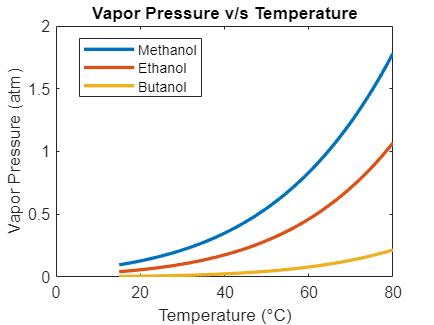


% Vapor Pressure Plot 
plot(T,P_methanol,LineWidth=2); 
hold on; 
plot(T,P_ethanol,LineWidth=2); 
plot(T,P_butanol,LineWidth=2); 
title("Vapor Pressure v/s Temperature"); 
xlabel("Temperature (°C)"); 
ylabel("Vapor Pressure (atm)"); 
legend("Methanol","Ethanol","Butanol", Location = 'best'); 
hold off 

% Relative Volatility Calculation  
alpha_ME = P_methanol./ P_ethanol % Methanol and Ethanol  

alpha_ME =     2.3014    2.2913    2.2813    2.2715    2.2617    2.2521    2.2426    2.2332    2.2238    2.2146    2.2055    2.1965    2.1876    2.1788    2.1700    2.1614    2.1529    2.1444    2.1361    2.1278    2.1196    2.1115    2.1035    2.0955    2.0877    2.0799    2.0722    2.0646    2.0571    2.0496    2.0422    2.0349    2.0277    2.0205    2.0134    2.0064    1.9994    1.9925    1.9857    1.9789    1.9722    1.9656    1.9591    1.9526    1.9461    1.9397    1.9334    1.9272    1.9210    1.9148


alpha_EB = P_ethanol./ P_butanol  % Ethanol and Butanol 

alpha_EB =     9.8087    9.7112    9.6154    9.5214    9.4292    9.3386    9.2496    9.1623    9.0765    8.9922    8.9094    8.8281    8.7482    8.6696    8.5925    8.5166    8.4421    8.3688    8.2967    8.2259    8.1562    8.0877    8.0203    7.9541    7.8889    7.8248    7.7617    7.6996    7.6386    7.5785    7.5193    7.4611    7.4038    7.3474    7.2918    7.2371    7.1833    7.1303    7.0780    7.0266    6.9759    6.9260    6.8769    6.8285    6.7807    6.7337    6.6874    6.6417    6.5967    6.5524


alpha_MB = P_methanol./ P_butanol % Methanol and Butanol

alpha_MB =    22.5734   22.2510   21.9359   21.6276   21.3262   21.0314   20.7429   20.4607   20.1846   19.9143   19.6498   19.3908   19.1373   18.8890   18.6459   18.4078   18.1746   17.9461   17.7222   17.5028   17.2878   17.0771   16.8706   16.6681   16.4696   16.2749   16.0840   15.8967   15.7130   15.5328   15.3560   15.1826   15.0124   14.8453   14.6813   14.5204   14.3623   14.2072   14.0548   13.9052   13.7583   13.6140   13.4722   13.3329   13.1961   13.0617   12.9295   12.7997   12.6721   12.5466


alpha_BB = P_butanol./P_butanol

alpha_BB =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


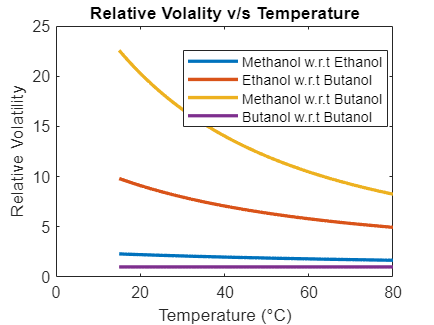

plot(T,alpha_ME,LineWidth=2); 
hold on; 
plot(T,alpha_EB,LineWidth=2); 
plot(T,alpha_MB,LineWidth=2);
plot(T,alpha_BB,LineWidth=2);
title("Relative Volality v/s Temperature"); 
xlabel("Temperature (°C)"); 
ylabel("Relative Volatility"); 
legend("Methanol w.r.t Ethanol","Ethanol w.r.t Butanol","Methanol w.r.t Butanol","Butanol w.r.t Butanol",Location = 'best'); 
hold off 


%Total Reflux Vapor Pressures 
T_bottom_tr = 76.6; 
T_top_tr= 63.3;

P_methanol_top_tr = 10.^(A_m - B_m./(C_m+T_top_tr)); 
P_methanol_top_tr = P_methanol_top_tr./760 

P_methanol_top_tr = 0.9509


P_methanol_bottom_tr = 10.^(A_m - B_m./(C_m+T_bottom_tr)); 
P_methanol_bottom_tr = P_methanol_bottom_tr./760 

P_methanol_bottom_tr = 1.5766


P_ethanol_top_tr = 10.^(A_e - B_e./(C_e+T_top_tr)); 
P_ethanol_top_tr = P_ethanol_top_tr./760 

P_ethanol_top_tr = 0.5342


P_ethanol_bottom_tr = 10.^(A_e - B_e./(C_e+T_bottom_tr)); 
P_ethanol_bottom_tr = P_ethanol_bottom_tr./760 

P_ethanol_bottom_tr = 0.9336


P_butanol_top_tr = 10.^(A_b - B_b./(C_b+T_top_tr)); 
P_butanol_top_tr = P_butanol_top_tr./760 

P_butanol_top_tr = 0.0948


P_butanol_bottom_tr = 10.^(A_b - B_b./(C_b+T_bottom_tr)); 
P_butanol_bottom_tr = P_butanol_bottom_tr./760 

P_butanol_bottom_tr = 0.1841



% Relative Volatility Calculation
% Methanol and Ethanol 
alpha_ME_top_tr = P_methanol_top_tr./ P_ethanol_top_tr 

alpha_ME_top_tr = 1.7802

alpha_ME_bottom_tr = P_methanol_bottom_tr./ P_ethanol_bottom_tr 

alpha_ME_bottom_tr = 1.6887


% Ethanol and Butanol 
alpha_EB_top_tr = P_ethanol_top_tr./ P_butanol_top_tr 

alpha_EB_top_tr = 5.6359

alpha_EB_bottom_tr = P_ethanol_bottom_tr./ P_butanol_bottom_tr 

alpha_EB_bottom_tr = 5.0717


% Methanol and Butanol 
alpha_MB_top_tr = P_methanol_top_tr./ P_butanol_top_tr 

alpha_MB_top_tr = 10.0329

alpha_MB_bottom_tr = P_methanol_bottom_tr./ P_butanol_bottom_tr

alpha_MB_bottom_tr = 8.5644


%R = 1.9
T_bottom = 79.4

T_bottom = 79.4000

T_top= 64.8

T_top = 64.8000


P_methanol_top = 10.^(A_m - B_m./(C_m+T_top)); 
P_methanol_top = P_methanol_top./760 

P_methanol_top = 1.0089


P_methanol_bottom = 10.^(A_m - B_m./(C_m+T_bottom)); 
P_methanol_bottom = P_methanol_bottom./760 

P_methanol_bottom = 1.7443


P_ethanol_top = 10.^(A_e - B_e./(C_e+T_top)); 
P_ethanol_top = P_ethanol_top./760 

P_ethanol_top = 0.5703


P_ethanol_bottom = 10.^(A_e - B_e./(C_e+T_bottom)); 
P_ethanol_bottom = P_ethanol_bottom./760 

P_ethanol_bottom = 1.0437


P_butanol_top = 10.^(A_b - B_b./(C_b+T_top)); 
P_butanol_top = P_butanol_top./760 

P_butanol_top = 0.1025


P_butanol_bottom = 10.^(A_b - B_b./(C_b+T_bottom)); 
P_butanol_bottom = P_butanol_bottom./760 

P_butanol_bottom = 0.2100



% Relative Volatility Calculation
% Methanol and Ethanol 
alpha_ME_top = P_methanol_top./ P_ethanol_top 

alpha_ME_top = 1.7691

alpha_ME_bottom = P_methanol_bottom./ P_ethanol_bottom 

alpha_ME_bottom = 1.6712


% Ethanol and Butanol 
alpha_EB_top = P_ethanol_top./ P_butanol_top 

alpha_EB_top = 5.5649

alpha_EB_bottom = P_ethanol_bottom./ P_butanol_bottom 

alpha_EB_bottom = 4.9695


% Methanol and Butanol 
alpha_MB_top = P_methanol_top./ P_butanol_top 

alpha_MB_top = 9.8447

alpha_MB_bottom = P_methanol_bottom./ P_butanol_bottom

alpha_MB_bottom = 8.3053


%R=1
T_bottom = 82.3

T_bottom = 82.3000

T_top= 65.7

T_top = 65.7000


P_methanol_top = 10.^(A_m - B_m./(C_m+T_top)); 
P_methanol_top = P_methanol_top./760 

P_methanol_top = 1.0452


P_methanol_bottom = 10.^(A_m - B_m./(C_m+T_bottom)); 
P_methanol_bottom = P_methanol_bottom./760 

P_methanol_bottom = 1.9332

P_ethanol_top = 10.^(A_e - B_e./(C_e+T_top)); 
P_ethanol_top = P_ethanol_top./760 

P_ethanol_top = 0.5930


P_ethanol_bottom = 10.^(A_e - B_e./(C_e+T_bottom)); 
P_ethanol_bottom = P_ethanol_bottom./760 

P_ethanol_bottom = 1.1689


P_butanol_top = 10.^(A_b - B_b./(C_b+T_top)); 
P_butanol_top = P_butanol_top./760 

P_butanol_top = 0.1074


P_butanol_bottom = 10.^(A_b - B_b./(C_b+T_bottom)); 
P_butanol_bottom = P_butanol_bottom./760 

P_butanol_bottom = 0.2401



% Relative Volatility Calculation
% Methanol and Ethanol 
alpha_ME_top = P_methanol_top./ P_ethanol_top 

alpha_ME_top = 1.7625

alpha_ME_bottom = P_methanol_bottom./ P_ethanol_bottom 

alpha_ME_bottom = 1.6538


% Ethanol and Butanol 
alpha_EB_top = P_ethanol_top./ P_butanol_top 

alpha_EB_top = 5.5233

alpha_EB_bottom = P_ethanol_bottom./ P_butanol_bottom 

alpha_EB_bottom = 4.8689


% Methanol and Butanol 
alpha_MB_top = P_methanol_top./ P_butanol_top 

alpha_MB_top = 9.7348

alpha_MB_bottom = P_methanol_bottom./ P_butanol_bottom

alpha_MB_bottom = 8.0522